# Ejercicio puntuable - LSE

## Enunciado

Los sensores reales presentan ciertas limitaciones  físicas en cuanto al rango y campo de visión. Modifica el ejercicio anterior para  contemplar que el sensor sólo proporciona medidas en un rango limitado 𝑟𝑟𝑙𝑙 y una  orientación limitada ±𝛼𝛼 con respecto a la pose del robot. Podría darse el caso que no  existieran landmarks en el campo de visión del sensor, con lo que el robot no dispondría de información sensorial en una iteración

Aumenta el número de Landmarks a 10 y  considera el caso particular de un sensor con  un rango máximo de 20m de alcance, y un FOV  de ±60º

Indica claramente en la memoria como tratas  el caso de no tener suficientes observaciones,  y muéstralo en las gráficas de posición y de  error. Añade/explica solo la parte del código  que has modificado

## Solución

Inicializamos

clc;
clear all; 
addpath(['auxmatlab/aux_functions'], 'auxmatlab/aux_functions_prob', 'p03lab02');

Definimos la función crear_mapa para generar y visualizar los Landmarks

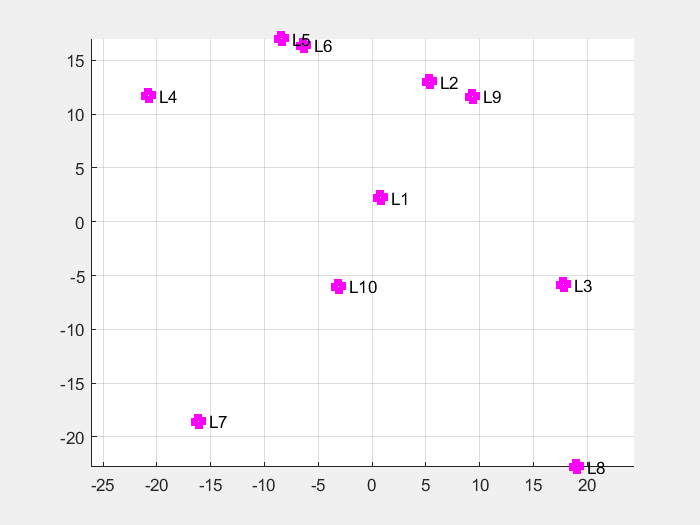

Mapa={};
Mapa.nLandmarks = 10;
Mapa.Size = 50;      
Mapa.Landmarks = crear_landmarks(Mapa);

Definimos la función leer_sensores que devuelve las distancias teniendo en cuenta el rango del sensor y orientación del robot

Robot={};
Robot.xTrue=[0 0 pi/2]' % posición inicial del robot

Robot = struct with fields:
    xTrue: [3×1 double]


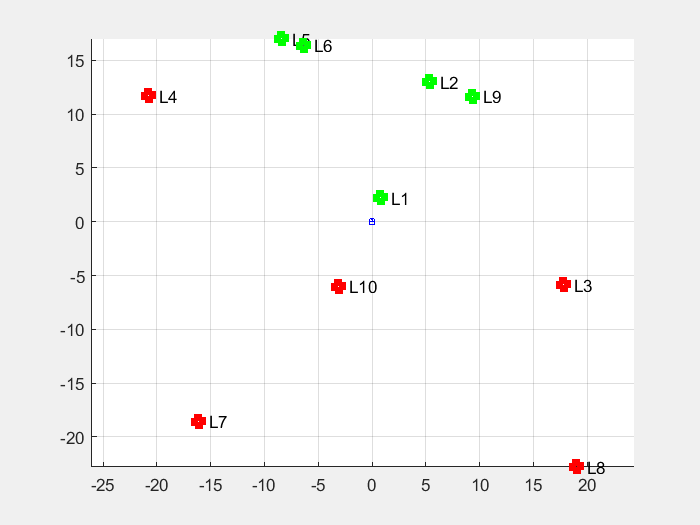

Robot.xOdom=[0 0 pi/2]';
Robot.plot = drawrobot(Robot.xTrue, 'b');
Robot.inc_x = 1;
Robot.inc_phi = pi/2;
Robot.u_stdx = 0.5;
Robot.u_stdy = 0.5;
Robot.u_stdphi = 0.5*pi/180;
Robot.std = diag([Robot.u_stdx, Robot.u_stdy, Robot.u_stdphi]);
Robot.U = Robot.std .^ 2;
    
Sensor={};
Sensor.var_d=0.05^2; % varianza del sensor de distancia
Sensor.std_d = sqrt(Sensor.var_d); % desviación típica
Sensor.rango=20; % rango lineal del sensor en metros
Sensor.alfa=90; % rango angular (FOV=+/-alfa) en grados

Sensor.z = leer_distancias(Mapa, Robot, Sensor);

Definimos la función estimar_posicion para cubrir toda la casuística de estimaciones

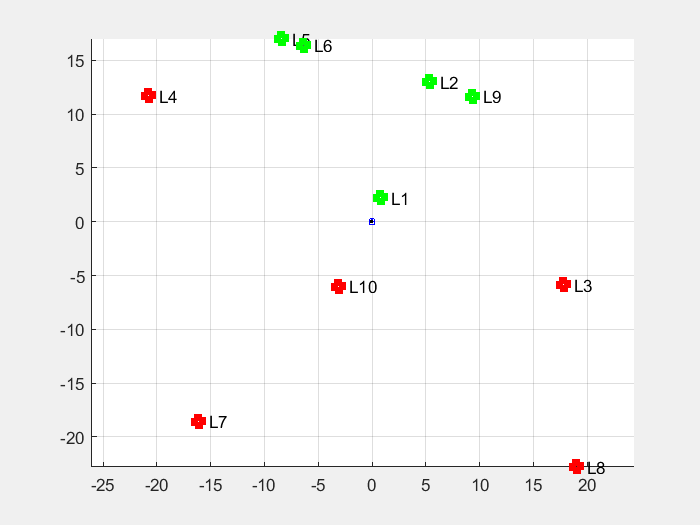

Lse={};
Lse.max_iter = 100;
Lse.tolerance = 1.0e-09;  
Robot.xEst = estimar_posicion(Mapa, Robot, Sensor, Lse);

Realizamos el cuadrado

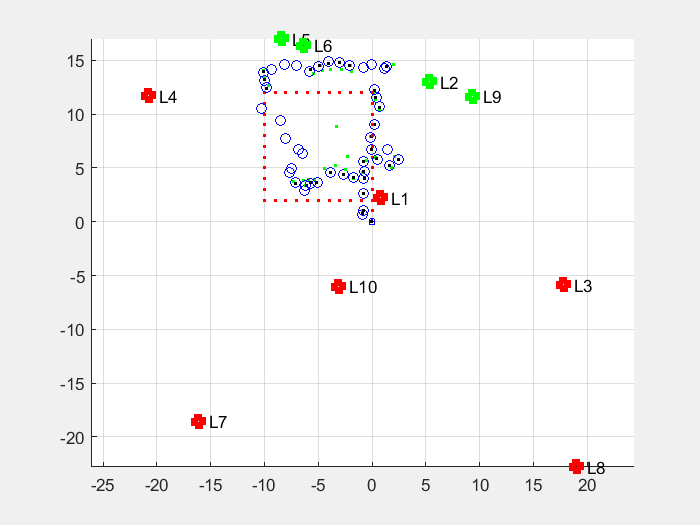

num_loops = 44;
loc_error = zeros(num_loops,1);
odo_error = zeros(num_loops,1);
num_sensors = zeros(num_loops,1);

for i=1:num_loops
    if (mod(i,11)==0)
        u=[0 0 Robot.inc_phi]'; % giro en cada esquina
    else
        u=[Robot.inc_x 0 0]'; % línea recta en el resto
    end

    % 10 Update xOdom: where the robot thinks it is
    Robot.xOdom = pose_comp(Robot.xOdom, u);

     % 11 Simulate real movement with noise
    noise = Robot.std*randn(3,1);
    uNoisy = pose_comp(u, noise);
    Robot.xTrue = pose_comp(Robot.xTrue, uNoisy);

    % 12 Estimate position from sensors
    Sensor.z = leer_distancias(Mapa, Robot, Sensor);
    Robot.xEst = estimar_posicion(Mapa, Robot, Sensor, Lse);

    % 13 Plot robot positions (without orientation)
    plot(Robot.xTrue(1),Robot.xTrue(2),'bo');   % Real Position (Ground Truth with Noise)
    plot(Robot.xOdom(1),Robot.xOdom(2),'r.');   % Odometry or ideal (Noise-free)

    %--------------
    loc_error(i) = sqrt((Robot.xTrue(1)-Robot.xEst(1))^2+(Robot.xTrue(2)-Robot.xEst(2))^2);    
    odo_error(i) = sqrt((Robot.xTrue(1)-Robot.xOdom(1))^2+(Robot.xTrue(2)-Robot.xOdom(2))^2);
    num_sensors(i) = length(Sensor.z(Sensor.z>1));

    pause(0.1);
end

## FINAL PLOTS

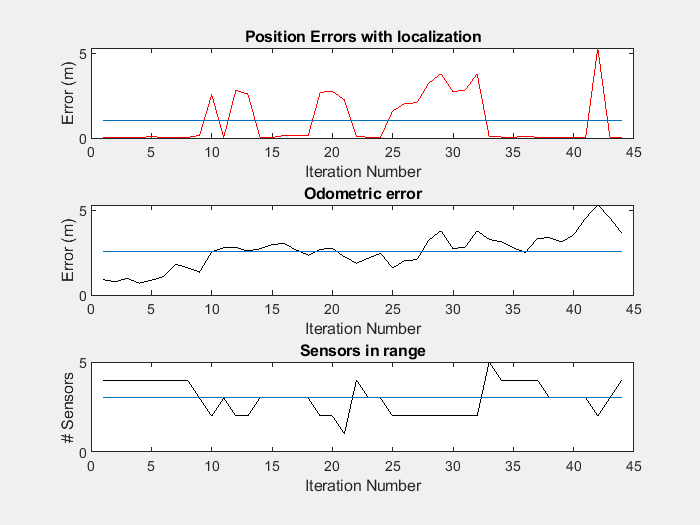

% 21 show average errors and their evolution.
avg_loc_error = mean(loc_error);
avg_odo_error = mean(odo_error);
avg_num_sensors = mean(num_sensors);

figure(2);
set(gcf,'Visible','on');
subplot(311); 
plot(loc_error,'r'); 
hold on; 
line([1 size(loc_error,1)],[avg_loc_error avg_loc_error]); 
title('Position Errors with localization');
xlabel('Iteration Number');
ylabel('Error (m)');

subplot(312); 
plot(odo_error,'k'); 
hold on; 
line([1 size(odo_error,1)],[avg_odo_error avg_odo_error]); 
title('Odometric error');
xlabel('Iteration Number');
ylabel('Error (m)');

subplot(313); 
plot(num_sensors,'k'); 
hold on; 
line([1 size(num_sensors,1)],[avg_num_sensors avg_num_sensors]); 
title('Sensors in range');
xlabel('Iteration Number');
ylabel('# Sensors');